# Time constant analysis from RBD ammeter

Script to plot the time constant of the detector using the RBD ammeter.

#### Import the data and chop it up

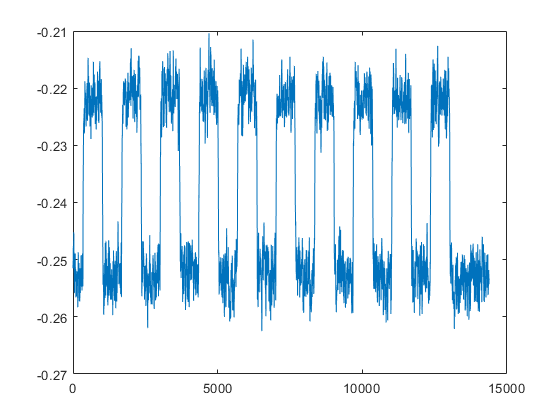



load('Data/ResponseTimeRBD.mat')

I=responseTimeRBD;

N=length(I);

figure;plot(I)



%Points to chop at
chop_inds=1:666:13500;

N_chop=length(chop_inds);

for n_chop=1:N_chop-1
    data_list{n_chop}=responseTimeRBD(chop_inds(n_chop):chop_inds(n_chop+1)-1);
end






## Old script from here 

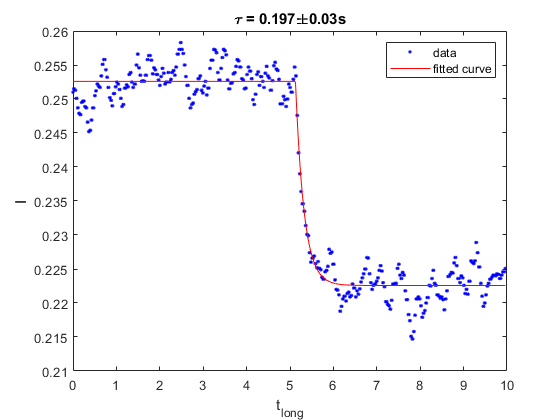

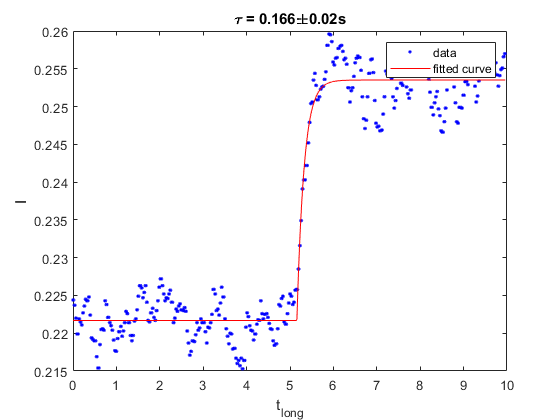

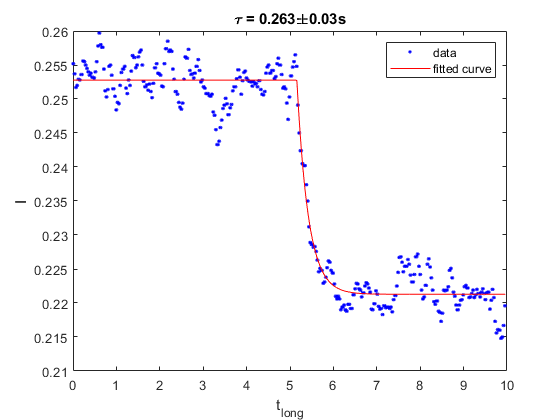

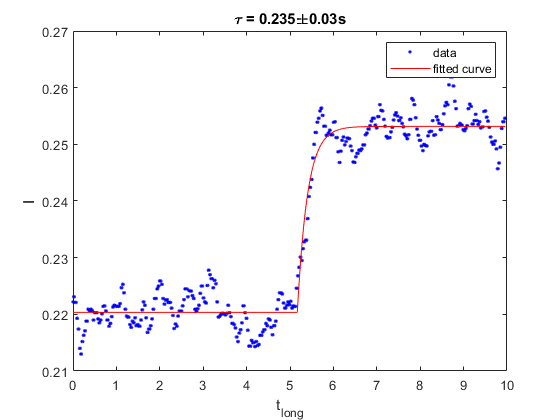

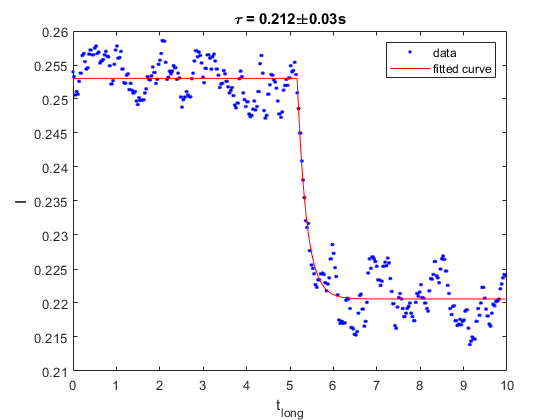

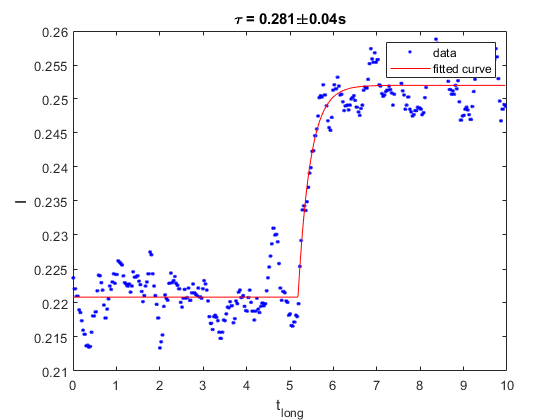

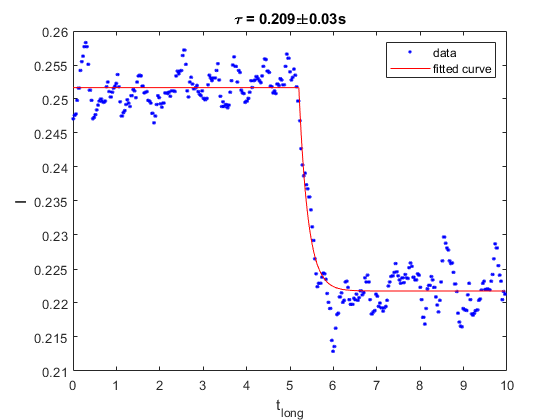

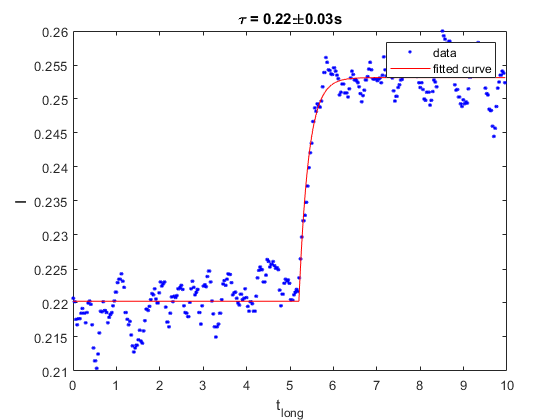



%Initialise memory

N_files=N_chop-1;

clip_size=150;

a=NaN*zeros(N_files,1);
b=NaN*zeros(N_files,1);
c=NaN*zeros(N_files,1);
b_error=NaN*zeros(N_files,1);
I_clip=NaN*zeros(2*clip_size+1,N_files);


%Main loop over each data set
for n=1:N_files
    
    %Grab data for this chopped set
    I=data_list{n};
    
    
    %Generate time series and flip to positive current
    I(end)=[];
    I=-1*I;
    N_long=length(I);
    
    t_long=0:15e-3:(N_long-1)*15e-3;
    
    
    %% Fit: 'untitled fit 1'.
    [xData, yData] = prepareCurveData( t_long', I );
    
    
    %Main fit happens here, it uses a piecewise function that fits a
    %constant and then an exponential decay.
    
    
    % Set up fittype and options.
    ft = fittype( '(a+c)*((x-x0)<=0)+((x-x0)>=0)*(a*exp(-(x-x0)/b)+c)', 'independent', 'x', 'dependent', 'y' );
    opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
    opts.Display = 'Off';
    
    
    %Flip if going up or down to make the fitting a bit easier
    if 1-mod(n,2)
        opts.StartPoint = [-0.01 0.3 0.2 4];
    else
        opts.StartPoint = [0.01 0.3 0.2 4];
    end
    
    % Fit model to data.
    [fitresult, gof] = fit( xData, yData, ft, opts );
    
    % Plot fit with data.
    figure;%( 'Name', 'untitled fit 1' );
    h = plot( fitresult, xData, yData );
    %legend( h, 'I vs. t_{long', 'untitled fit 1', 'Location', 'NorthEast' );
    % Label axes
    xlabel t_{long}
    ylabel I
    % grid on
    
    
    %Calculate error on measurement and save results
    error=confint(fitresult);
    
    a(n)=fitresult.a;
    
    c(n)=fitresult.c;
    
    b(n)=fitresult.b;
    b_error(n)=(error(2,2)-error(1,2))/2;
    
    [~,ind]=min(abs(t_long-fitresult.x0));
    
    I_clip(:,n)=yData(ind-clip_size:ind+clip_size);
    
    title(['\tau = ',num2str(b(n),3),'\pm',num2str(b_error(n),1),'s'])
    
    
end


%Find weighted mean of each time constant and the error
b_mean=sum(b./(b_error.^2))/sum(b_error.^(-2));
b_mean_error=sqrt(1/sum(b_error.^(-2)));

disp(['\tau = ',num2str(b_mean,3),'+-',num2str(b_mean_error,1),'s'])

\tau = 0.198+-0.006s


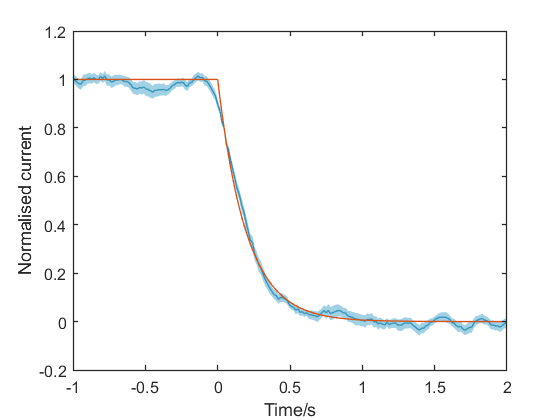


%Create average values for average plot
av_vals=NaN*zeros(2*clip_size+1,N_files);
for k=1:N_files
    av_vals(:,k)=(I_clip(:,k)-(c(k)))/(a(k));
end

t_clip=-clip_size*15e-3:15e-3:clip_size*15e-3;



I_model=(t_clip<=0)+(t_clip>0).*(exp(-t_clip./b_mean));

I_int=mean(av_vals,2);
I_std=std(av_vals,[],2)/sqrt(10);

%  figure
%  %plot(t_clip,I_int,'x','MarkerSize',6,'LineWidth',1)
%   errorbar(t_clip,I_int,I_std,'x','MarkerSize',6,'LineWidth',1)

%Plot averaged data against the model to see how it compares
fig_h=figure;
options.x_axis=t_clip;
options.error='sem';
options.handle=fig_h;
options.color_area = [128 193 219]./255;    % Blue theme
options.color_line = [ 52 148 186]./255;
%options.color_area = [243 169 114]./255;    % Orange theme
%options.color_line = [236 112  22]./255;
options.alpha      = 0.75;
options.line_width = 1;

options.marker_size=3;
options.marker='none';%'x';

plot_areaerrorbar(av_vals',options)


hold on
plot(t_clip,I_model,'LineWidth',1,'Color',	[0.8500, 0.3250, 0.0980])
xlim([-1 2])
xlabel('Time/s')
ylabel('Normalised current')
set(gca,'FontSize',12,'LineWidth',1)


%print -dpdf ..\Figures\TC_av2.pdf
%exportgraphics(gca,'..\Figures\TC_av2.pdf')

